# **OFDM Transmitter Using Software-Defined Radio **

This example shows how to design an orthogonal frequency division multiplexing (OFDM) transmitter for a single-input single-output (SISO) channel using a software-defined radio (SDR).  

This example details the physical-layer transmission protocol of the OFDM system that mimics typical synchronization signals, reference symbols, control channels, and data channels.  The OFDM transmission system processing includes cyclic redundancy check(CRC), encoding, scrambling, convolutional encoding, modulation, filtering, channel distortion. 

The [OFDM Receiver Using Software-Defined Radio](docid:usrpradio_ug#mw_e5f85a9c-44ee-4f85-9a77-c56616e2b097) example receives and demodulates the OFDM signal transmitted by this example.

## Required Hardware and Software

To run this example you will need one of the following hardware and the corresponding support package

- 200-Series USRP Radio (B2xx) and [Communications Toolbox Support Package for USRP Radio](https://www.mathworks.com/hardware-support/usrp.html). For information on how to map an NI™ USRP device to an Ettus Research 200-series USRP device, see [Supported Hardware and Required Software](docid:usrpradio_ug#buzc7a6-1).

- 300-Series USRP Radio (X3xx or N3xx) and [Wireless Testbench Support Package for NI USRP Radios](https://www.mathworks.com/hardware-support/ni-usrp-radios.html). For information on how to map an NI USRP device to an Ettus Research 300-series USRP device, see [Supported Radio Devices](docid:wt_gs#mw_74eb94c7-dcbc-40dc-8a56-cc7bc0124002).

- ADALM-PLUTO radio and the Communications Toolbox Support Package for Analog Devices® ADALM-PLUTO Radio software

## **Set OFDM Frame Parameters**

Set the OFDM parameters, including the FFT length, cyclic prefix length, and number of subcarriers. The pilot subcarrier spacing and channel bandwidth parameters are fixed at 30 KHz and 3 MHz, respectively.

After configuring the OFDM parameters, you must set the data parameters. Set the modulation order, code rate, number of symbols per frame, and the number of frames per transmission. The possible modulation schemes are BPSK, QPSK and 16-QAM and the possible code rates are 1/2 and 2/3. The OFDM parameters and the data parameters must be common to both transmitter and receiver.

You can enable or disable the scopes for visualization, however for long simulations, it is recommended to disable the scope. To control the diagnostic output, enable or disable the verbosity as needed.

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % FFT length
OFDMParams.CPLength               = 32;    % Cyclic prefix length
OFDMParams.NumSubcarriers         = 72;    % Number of sub-carriers in the band
OFDMParams.Subcarrierspacing      = 30e3;  % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = 3e6;   % Bandwidth of the channel 3 MHz

% Data Parameters
dataParams.modOrder       = 256;   % Data modulation order
dataParams.coderate       = "3/4";   % Code rate
dataParams.numSymPerFrame = 30;   % Number of data symbols per frame 20 for setup1
dataParams.numFrames      = 10000;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = false;                    % Switch to enable or disable the data diagnostic output

## Initialize Transmitter Parameters

Assign the name of the radio you are using for transmitting the OFDM signal to the variable `radioDevice`. Set the receiver gain and operating center frequency.

radioDevice            = "PLUTO";  % Choose the radio device for transmission
centerFrequency        = 865e6;  % Center Frequency
gain                   = -10;  % Set radio gain

The `helperOFDMSetParamsSDR` function initializes transmit-specific and common transmitter/receiver parameters required for the OFDM simulation and the `helperGetRadioParams` function initializes the parameters required for the transmitter System object™ radio. 

[sysParam,txParam,trBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate               = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal
ofdmTx                   = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain);

% Get the radio transmitter and spectrum analyzer system object system object for the user to visualize the transmitted waveform.
[radio,spectrumAnalyze] = helperGetRadioTxObj(ofdmTx);

## Generate Transmitter Waveform 

### **Transmit Frame Structure**

A transport block contains user data and control information. The OFDM transmitter transmits one transport block per frame. The transport block size varies based on several factors: the number of active subcarriers, the number of pilot subcarriers, modulation order, coding rate, CRC length, encoder constraint length, and the number of data symbols per frame.

The transmission grid populates signals and channels on a per-frame basis. The figure below shows one transmission frame of 28 OFDM symbols with FFT length of 128.

**Synchronization Symbol (SS)**

A synchronization (sync) signal is transmitted as the first symbol in the frame. The sync signal consists of a 62-subcarriers signal centered at DC generated using a ZadOff-Chu. This signal is designed to be bandwidth agnostic, meaning that all transmitters can transmit this signal regardless of the allocated bandwidth for that cell. The signal is meant to be detected by receivers to positively detect the cell signal and identify the frame boundary (the start of the frame).

**Reference Symbol (RS)**

The next symbol in the transmit frame is the reference symbol. Known at both the transmitter and receiver, the reference symbol allows the receiver to compare the received reference symbol with the known reference symbol to estimate the channel. The receiver then compensates for the channel distortion between the transmitter and receiver.

**Header Symbol**

The header symbol conveys the bandwidth, subcarrier modulation scheme, and code rate of the OFDM data symbols to help the receiver decode the transmitted frame. The information is important enough that it is transmitted with large signaling and coding margins to maximize correct decoding. Therefore, the symbol is coded at 1/2 rate with wide interleaving and modulated using BPSK. Since the channel distortion may change over time, the header symbol is transmitted immediately after the reference symbol to maximize the probability of correct reception. Because the bandwidth is not yet known, the header is always transmitted with a 72-subcarrier signal centered at DC.

**Pilot Signals**

Finally, to combat phase jitter seen at higher transmission frequencies, a pilot is transmitted at fixed subcarrier intervals within the data symbols to provide a phase reference to the receiver.

**DC and Guard Subcarriers**

Null subcarriers at the edge of the transmission spectrum are used to constrain spectral energy to a specified bandwidth. The subcarrier at DC is also nulled to keep the signal energy to within the linear range of the power amplifier.

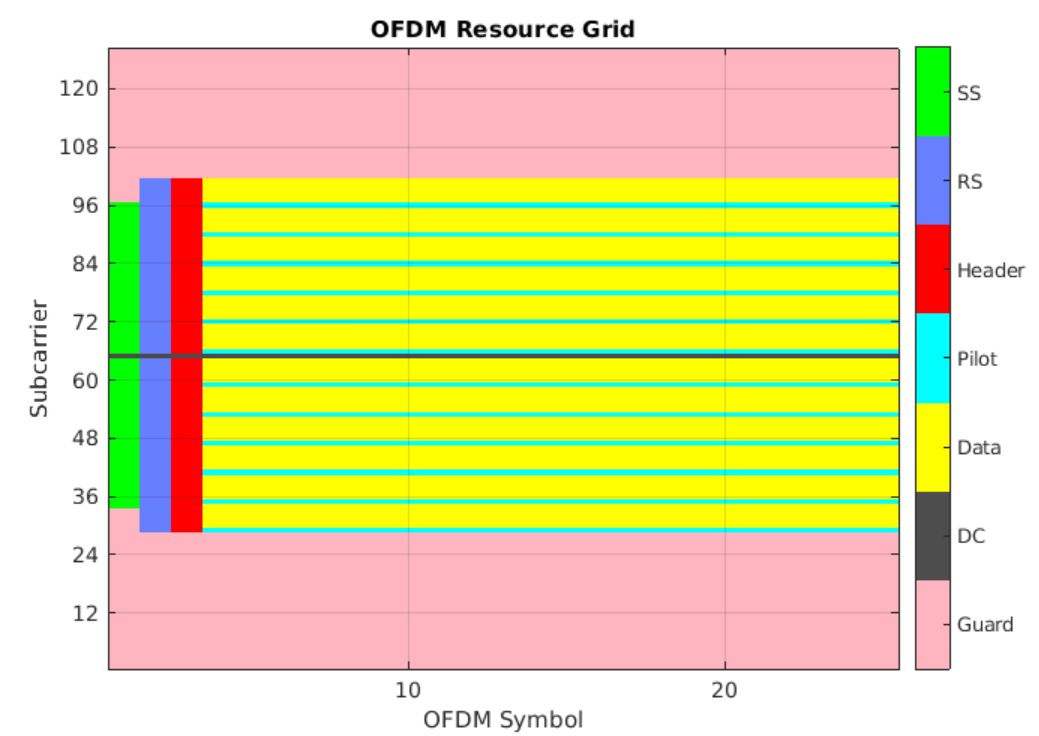

### Transmitter processing

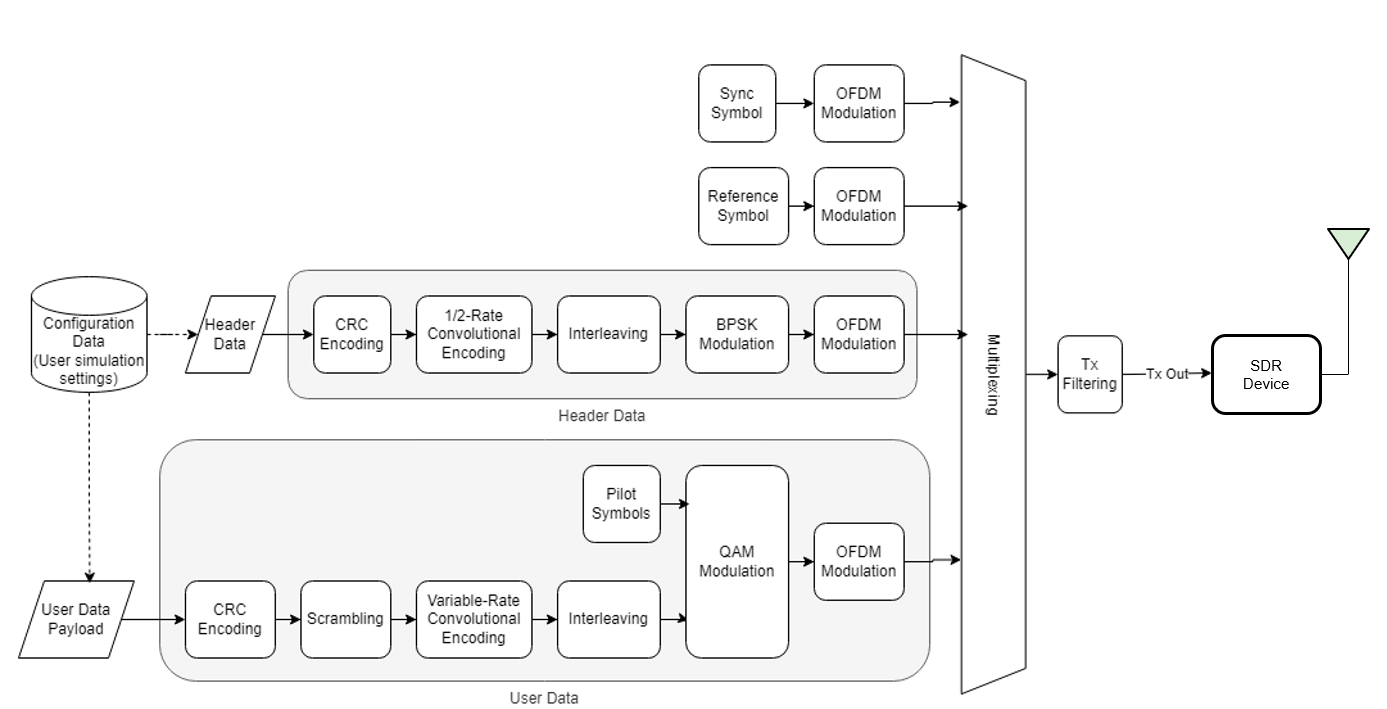

The data symbols comprise a single user populating a single transport block of data transmitted once per frame. A `comm.CRCGenerator` object computes the CRC for the transport block payload and appends it to the payload. The data is additively scrambled using a `comm.PNSequence` object to distribute the data power evenly across the transmission spectrum.  Interleaving is done with the `reshape` function to resist burst errors caused by deep fades. Convolutional encoding adds redundant bits for forward error correction and is done with the `convenc` function. Puncturing of the data increases data throughput by reducing the number of redundant bits. The transport block is modulated using the `qammod` function and is ready for transmission in an OFDM frame. All signals are OFDM-modulated using the `ofdmmod` function. The signal is filtered to reduce out-of-band emissions using dsp.`FIRFilter`, with coefficients generated using the `firpmord` and `firpm` filter design functions.

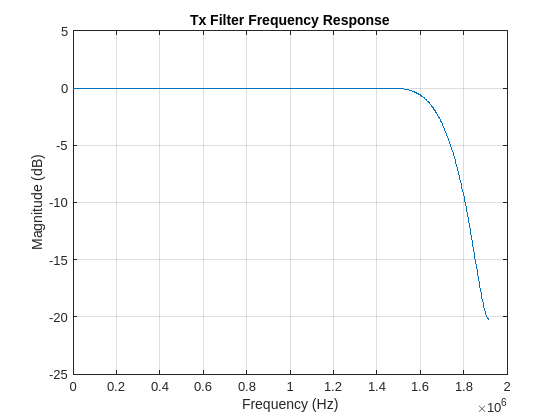


% Initialize transmitter
txObj = helperOFDMTxInit(sysParam);

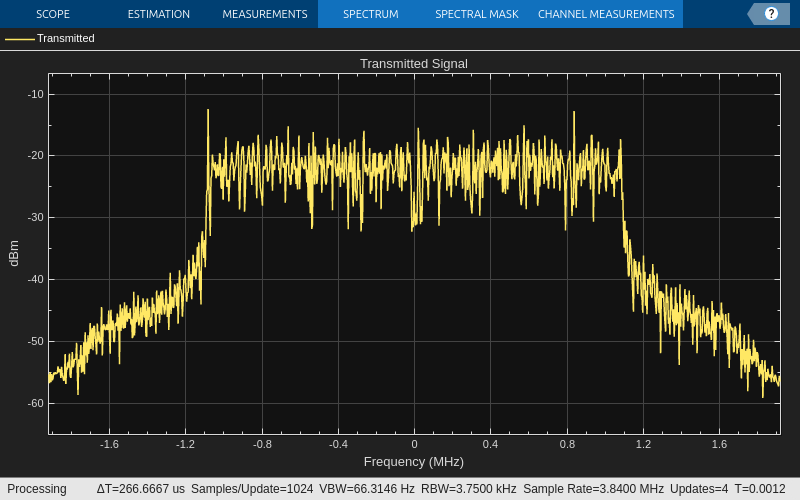

tunderrun = 0; % Initialize count for underruns

% A known payload is generated in the function helperOFDMSetParams with
% respect to the calculated trBlkSize
% Store data bits for BER calculations
txParam.txDataBits = trBlk;
[txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);

% Display the grid if verbosity flag is enabled
if dataParams.verbosity
    helperOFDMPlotResourceGrid(txGrid,sysParam);
end

% Repeat the data in a buffer for PLUTO radio to make sure there are less
% underruns. The receiver decodes only one frame from where the first
% synchroization signal is received
txOutSize = length(txOut);
if contains(radioDevice,'PLUTO') && txOutSize < 48000
    frameCnt = ceil(48000/txOutSize);
    txWaveform = zeros(txOutSize*frameCnt,1);
    for i = 1:frameCnt
        txWaveform(txOutSize*(i-1)+1:i*txOutSize) = txOut;
    end
else
    txWaveform = txOut;
end

if dataParams.enableScopes
    spectrumAnalyze(txOut);
end

## Transmit Over Radio

for frameNum = 1:sysParam.numFrames+1
    underrun = radio(txWaveform);
    tunderrun = tunderrun + underrun;  % Total underruns
end

## Establishing connection to hardware. This process can take several seconds.


% Clean up the radio System object
release(radio);

## Further Exploration

You can modify the initialization parameters in the `helperOFDMSetParamsSDR` and `helperOFDMTxInit` functions. Similarly, you can modify `helperOFDMPilotSignal` `helperOFDMRefSignal` `helperOFDMSyncSignal` helper functions to generate custom pilot, reference and synchronization signals respectively.

*Copyright 2023-2024 The MathWorks, Inc.*